## Test Parseval K-SVD

- Part1: Learning a K-SVD dictionary for the initial dictionary for Parseval K-SVD

clear all
close all
clc
Im = imread('boat256.png');
Im = double(Im);

Im_block_col = im2col(Im, [8,8], 'distinct'); %Im block
Im_block_col_mean = mean(Im_block_col);
Y = Im_block_col - Im_block_col_mean; % E(Yi) = 0, for all i

%K-SVD

%create overcomplete DCT frame
Pn = 16 ;
DCT=zeros(8,Pn);
for k=0:1:Pn-1,
    V=cos([0:1:7]'*k*pi/Pn);
    if k>0, V=V-mean(V); end;
    DCT(:,k+1)=V/norm(V);
end;
DCT=kron(DCT,DCT);

param.K = 256;
param.numIteration = 30;
param.InitializationMethod =  'GivenMatrix';
param.initialDictionary = DCT;
param.displayProgress = 1;
param.preserveDCAtom = 1;
param.L = 64;
param.errorFlag = 0;
param.errorGoal = 1.0e-8;
[D_svd, output] = KSVD(Y, param);

Iteration   2   max error norm is: 1.888e-12
Iteration   3   max error norm is: 2.4679e-12
Iteration   4   max error norm is: 2.5271e-12
Iteration   5   max error norm is: 2.9557e-12
Iteration   6   max error norm is: 1.5672e-12
Iteration   7   max error norm is: 1.5227e-12
Iteration   8   max error norm is: 2.6026e-12
Iteration   9   max error norm is: 1.3773e-12
Iteration   10   max error norm is: 2.7512e-12
Iteration   11   max error norm is: 2.8613e-12
Iteration   12   max error norm is: 2.4009e-12
Iteration   13   max error norm is: 1.8612e-12
Iteration   14   max error norm is: 1.8736e-12
Iteration   15   max error norm is: 1.3306e-12
Iteration   16   max error norm is: 3.0445e-12
Iteration   17   max error norm is: 2.7289e-12
Iteration   18   max error norm is: 2.9916e-12
Iteration   19   max error norm is: 3.0022e-12
Iteration   20   max error norm is: 1.3549e-12
Iteration   21   max error norm is: 2.403e-12
Iteration   22   max error norm is: 2.7588e-12
Iteration   23   max er

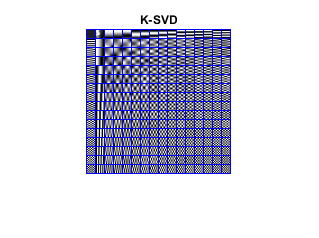

X = full(output.CoefMatrix);

KsvdIm = plot_8by8_frame(D_svd);
figure;
imshow(KsvdIm); title('K-SVD'); %show D_svd element in image

- Part2: Learning the Parseval K-SVD

Psi0 = D_svd;
Phi0 = D_svd + randn(size(D_svd, 1), size(D_svd, 2));
X0 = X;
maxIter = 50;
t = 1.0e-10;
rho = [0.1, 1.0e+8, 1.0e+8];
IsRecord = true;
ShowDetail = true;

[Psi, Phi, X, Record] = ParsevalKSVD(Y, Psi0, Phi0, X0, maxIter, t, rho, IsRecord, ShowDetail);

Iteration = 1
L=1.678e+11 , obj_rep=1.763e+07 , obj_total=6.112e+07 , con1=134.1     , con2=212.2     
Iteration = 2
L=2.93e+11  , obj_rep=8.285e+06 , obj_total=3.185e+07 , con1=386.3     , con2=79.05     
Iteration = 3
L=-7.906e+10, obj_rep=1.499e+07 , obj_total=3.922e+07 , con1=888.7     , con2=841.6     
Iteration = 4
L=1.381e+11 , obj_rep=1.794e+07 , obj_total=3.724e+07 , con1=211.8     , con2=432.2     
Iteration = 5
L=-7.241e+10, obj_rep=2.673e+07 , obj_total=9.891e+07 , con1=202.8     , con2=269.5     
Iteration = 6
L=4.174e+10 , obj_rep=2.25e+07  , obj_total=9.575e+07 , con1=37.99     , con2=432.9     
Iteration = 7
L=1.282e+11 , obj_rep=1.46e+07  , obj_total=4.805e+07 , con1=121.7     , con2=235.9     
Iteration = 8
L=9.994e+10 , obj_rep=1.619e+07 , obj_total=4.704e+07 , con1=64.97     , con2=319.3     
Iteration = 9
L=2.5e+10   , obj_rep=2.09e+07  , obj_total=4.858e+07 , con1=299.7     , con2=612.8     
Iteration = 10
L=4.765e+10 , obj_rep=1.833e+07 , obj_total=3.862e+07 , co

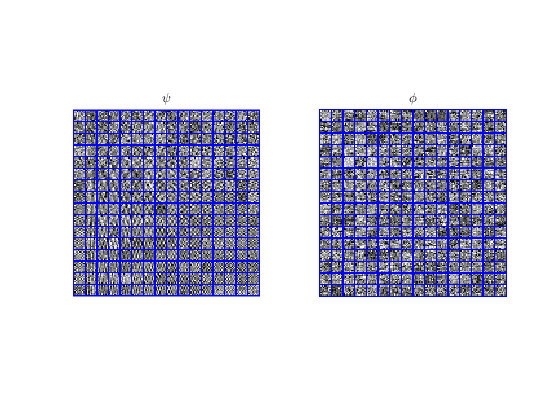


PsiIm = plot_8by8_frame(Psi); 
PhiIm = plot_8by8_frame(Phi);
figure;
subplot(1, 2, 1); imshow(PsiIm); title('$\psi$','Interpreter','latex');
subplot(1, 2, 2); imshow(PhiIm); title('$\phi$','Interpreter','latex');

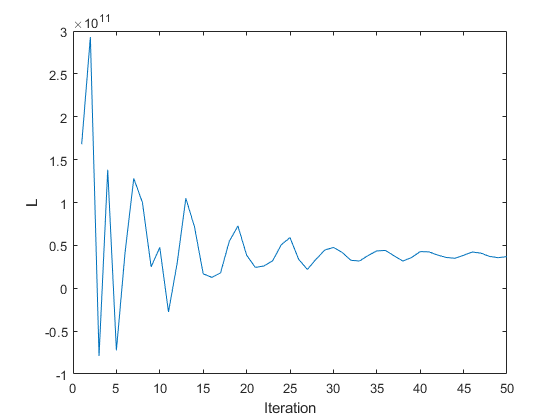


%Displaying the curve for the convergent behavior
figure;
plot(Record.augLag); xlabel('Iteration'); ylabel('L');

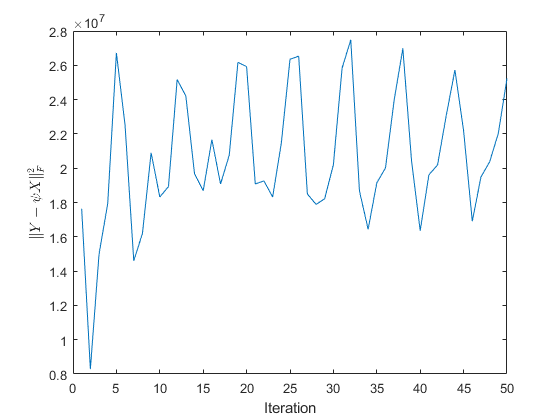


figure;
plot(Record.obj_rep); xlabel('Iteration'); ylabel('$\| Y - \psi X \|_F^2$', 'Interpreter','latex');

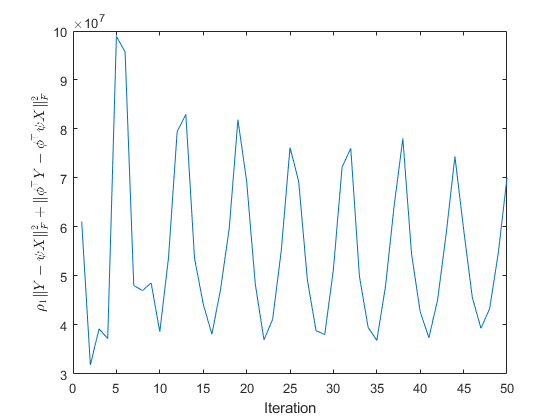


figure;
plot(Record.obj_total); xlabel('Iteration'); ylabel('$\rho_1 \| Y - \psi X \|_F^2 + \| \phi^\top Y -  \phi^\top \psi X \|_F^2$', 'Interpreter','latex');

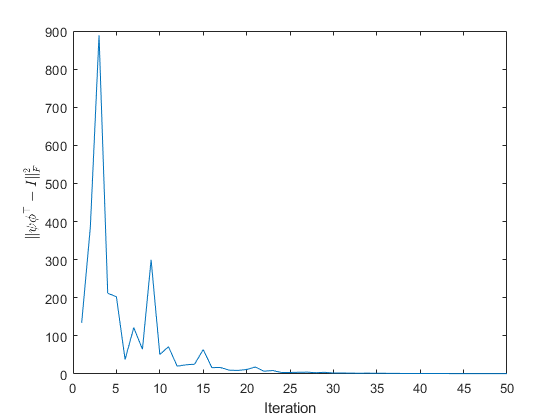


figure;
plot(Record.con1); xlabel('Iteration'); ylabel('$\| \psi \phi^\top - I \|_F^2$', 'Interpreter','latex');

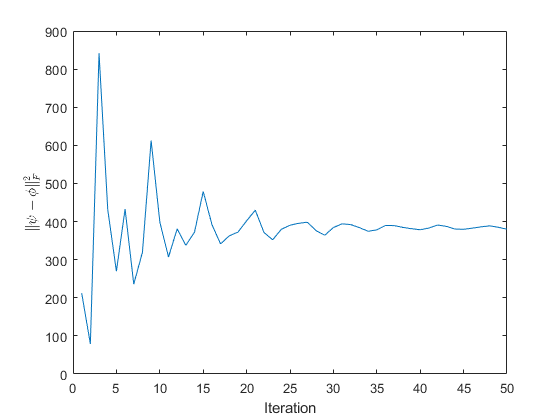


figure;
plot(Record.con2); xlabel('Iteration'); ylabel('$\| \psi - \phi \|_F^2$', 'Interpreter','latex');